## Task 1

tf = (5 * 60) % Readings for 5 Minutes

tf = 300

t = 0 :0.5: tf % 1 Reading per 0.5 Seconds

t =          0    0.5000    1.0000    1.5000    2.0000    2.5000    3.0000    3.5000    4.0000    4.5000    5.0000    5.5000    6.0000    6.5000    7.0000    7.5000    8.0000    8.5000    9.0000    9.5000   10.0000   10.5000   11.0000   11.5000   12.0000   12.5000   13.0000   13.5000   14.0000   14.5000   15.0000   15.5000   16.0000   16.5000   17.0000   17.5000   18.0000   18.5000   19.0000   19.5000   20.0000   20.5000   21.0000   21.5000   22.0000   22.5000   23.0000   23.5000   24.0000   24.5000


z = ones(1,601) % Total Readings in 5 Minutes

z =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1



% Part 1 - Noise Free Reading of X and Y
x = 24 * (z) % Thermometer X

x =     24    24    24    24    24    24    24    24    24    24    24    24    24    24    24    24    24    24    24    24    24    24    24    24    24    24    24    24    24    24    24    24    24    24    24    24    24    24    24    24    24    24    24    24    24    24    24    24    24    24


y = 24.5 * (z) % Thermometer Y

y =    24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000   24.5000



% Part 2 & 3 - Gaussian Noise on X and Y
x_n = 0.5 + 1.2.*randn(1,601)

x_n =     0.6045    0.3460    0.9045   -1.0494   -0.1961   -0.1459    2.4746   -1.2632    1.3011   -0.5425    1.4597   -0.5567    0.2524    2.4290    1.1695   -2.2932    0.7815    0.0243    2.5484    2.3088    1.7866    1.2073    0.9465    0.7365    0.2619   -1.2973   -0.2104    0.0759   -0.4657    0.3528    1.6850    1.5071    0.6487   -1.4178    0.2061   -0.9381    1.2331    2.1541    0.9581   -0.2401   -0.3058    0.0796    3.4745    0.2502    1.0811   -2.2958    2.7960    0.2661   -0.6686    0.6325


y_n = 0.8 + 1.5.*randn(1,601)

y_n =     1.8410    0.9096   -0.2173    4.5330    2.3749    2.9156    3.1572    0.6086    0.1422    2.5851   -0.3088    3.4447   -1.7075   -2.0077   -0.5860    0.9577    1.1212    1.1531    2.6716    0.4140    1.8318    1.0074    2.8500    4.1423    0.7655    0.0163    0.5678    0.6256    0.7016    0.4866    2.1344    2.8178    1.8590    1.2966    0.6653    2.5723   -0.7703    3.9713    3.7180   -0.9959    0.4673    0.8492   -1.7797   -0.9618    1.9301    0.7480   -1.0073   -0.0567    1.1544    5.2352


x2 = x + x_n

x2 =    24.6045   24.3460   24.9045   22.9506   23.8039   23.8541   26.4746   22.7368   25.3011   23.4575   25.4597   23.4433   24.2524   26.4290   25.1695   21.7068   24.7815   24.0243   26.5484   26.3088   25.7866   25.2073   24.9465   24.7365   24.2619   22.7027   23.7896   24.0759   23.5343   24.3528   25.6850   25.5071   24.6487   22.5822   24.2061   23.0619   25.2331   26.1541   24.9581   23.7599   23.6942   24.0796   27.4745   24.2502   25.0811   21.7042   26.7960   24.2661   23.3314   24.6325


y2 = y + y_n

y2 =    26.3410   25.4096   24.2827   29.0330   26.8749   27.4156   27.6572   25.1086   24.6422   27.0851   24.1912   27.9447   22.7925   22.4923   23.9140   25.4577   25.6212   25.6531   27.1716   24.9140   26.3318   25.5074   27.3500   28.6423   25.2655   24.5163   25.0678   25.1256   25.2016   24.9866   26.6344   27.3178   26.3590   25.7966   25.1653   27.0723   23.7297   28.4713   28.2180   23.5041   24.9673   25.3492   22.7203   23.5382   26.4301   25.2480   23.4927   24.4433   25.6544   29.7352


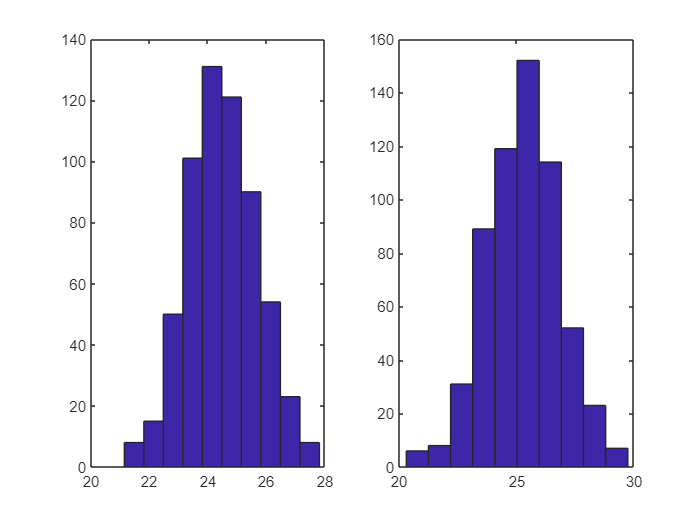


% Part 4 - Histograms of X and Y
figure(1)
subplot(1,2,1)
hist(x2)
subplot(1,2,2)
hist(y2)


% Part 5 - Mean, Median, Mode, & Variance
% X:
mean_x = mean(x2)

mean_x = 24.4899

median_x = median(x2)

median_x = 24.4511

mode_x = mode(x2)

mode_x = 21.1372

variance_x = var(x2)

variance_x = 1.4116

% Y:
mean_y = mean(y2)

mean_y = 25.2831

median_y = median(y2)

median_y = 25.2791

mode_y = mode(y2)

mode_y = 20.3095

variance_y = var(y2)

variance_y = 2.3944


% Part 6 - Systematic & Random Error
room_temp = 25 ;
% Systematic:
sys_error_x = mean_x - room_temp

sys_error_x = -0.5101

sys_error_y = mean_y - room_temp

sys_error_y = 0.2831

% Random:
rand_error_x = std(x2)

rand_error_x = 1.1881

rand_error_y = std(y2)

rand_error_y = 1.5474

## Task 2

mu = [2 3];
sigma = [1 0.8; 0.8 3];
Data = mvnrnd(mu, sigma, 10000)

Data =     2.3825    3.3075
    2.7598    4.6421
    1.1960    4.2053
    2.6470    4.1887
    1.2217    3.3887
    2.3191    2.0714
    2.1594    3.6829
    2.9578    5.7043
    1.8987    4.3631
    0.9350    2.3022


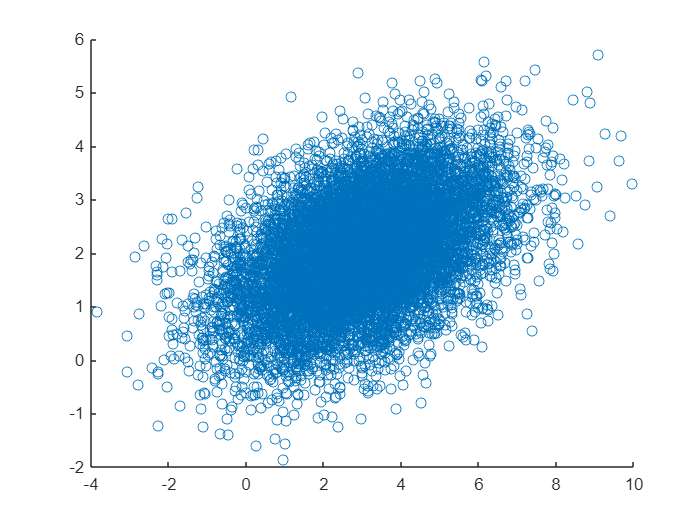

X = Data(:, 1) ; % 1st variable
Y = Data(:, 2) ; % 2nd variable

% Part 1 - X & Y Plot
figure(2)
scatter(Y , X)

% Part 2 - Correlation Coefficient 
mean_X = mean(X) ;
mean_Y = mean(Y) ;

a = X - mean_X ;
b = Y - mean_Y ;

Sx = std(X) ;
Sy = std(Y) ;

N = 10000 ;

r = sum(a .* b) / ((N-1)*Sx*Sy) % Correlation Coefficient Value

r = 0.4629


% Part 3 - Linear Model
b1 = sum( a .* b )/sum( ( a ).^2 ) % b1 Value

b1 = 0.7984

bo = mean_Y - (b1 * mean_X)        % bo Value

bo = 1.4001


% Part 4 - Plot
figure(3) % Scatter Plot Figure with Obtained Line
Y1 = bo + (b1 * X); 
scatter(X , Y)
hold on
p = polyfit(X,Y1,1) % p(1) should equal b1 & p(2) should equal bo

p =     0.7984    1.4001


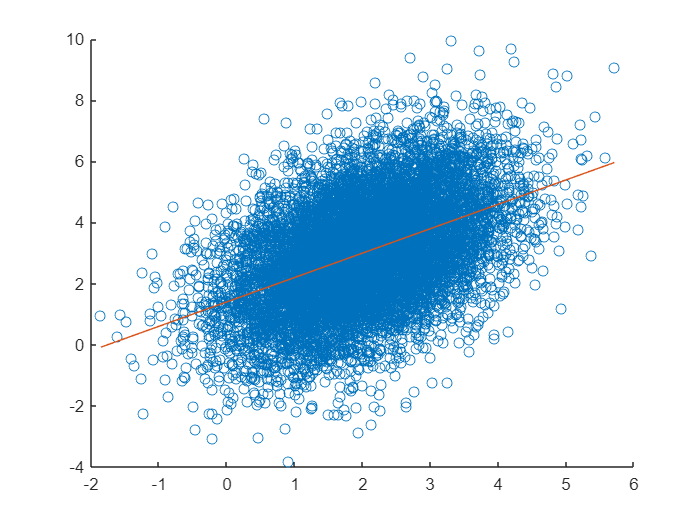

plot(X, Y1)
hold off

## Task 3

load Lab8_Task3.mat


fs ;
Ts = 1/fs ;
t = 0:Ts: 0.5

t =          0    0.0010    0.0020    0.0030    0.0040    0.0050    0.0060    0.0070    0.0080    0.0090    0.0100    0.0110    0.0120    0.0130    0.0140    0.0150    0.0160    0.0170    0.0180    0.0190    0.0200    0.0210    0.0220    0.0230    0.0240    0.0250    0.0260    0.0270    0.0280    0.0290    0.0300    0.0310    0.0320    0.0330    0.0340    0.0350    0.0360    0.0370    0.0380    0.0390    0.0400    0.0410    0.0420    0.0430    0.0440    0.0450    0.0460    0.0470    0.0480    0.0490


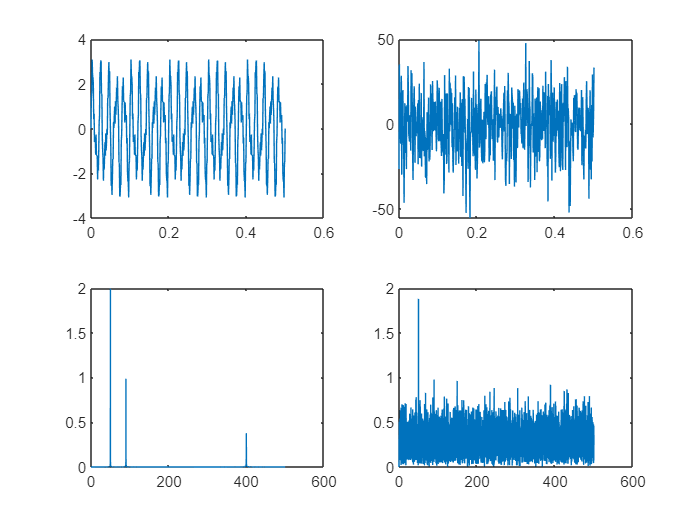

x1_m = x1(1:501);
x2_m = x2(1:501);

[X1, f1] = frft(x1 , fs) ;
[X2, f2] = frft(x2 , fs) ;


% Part 1 - Plot x1, x2, f-d representation of x1 & x2.figure(4)
subplot(2,2,1)
plot(t , x1_m)
subplot(2,2,2)
plot(t , x2_m)
subplot(2,2,3)
plot(f1, abs(X1))
subplot(2,2,4)
plot(f2 , abs(X2))


% Part 2 & 3 - Values and number of frequencies 
abs(X1)

ans =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001


abs(X2)'

ans =     0.0000    0.1791    0.0546    0.3186    0.2573    0.2855    0.3574    0.0891    0.5072    0.2013    0.3624    0.3076    0.4513    0.1871    0.1954    0.3124    0.3023    0.2533    0.4669    0.4208    0.2545    0.2175    0.0753    0.4047    0.2169    0.5407    0.2508    0.2020    0.1666    0.3412    0.2567    0.0941    0.2046    0.3768    0.2614    0.1777    0.2406    0.4783    0.6338    0.3834    0.1713    0.2419    0.4322    0.3716    0.3507    0.1180    0.3289    0.1749    0.3150    0.3153


It increased the number of various frequencies greatly. While we only had few values of frequencies, adding noise created countless more frequencies with different values.